Parameters

SFl = 1 % length scaling factor 

SFl = 1

lt = SFl*0.0725 ;% length of the thigh segment in metres
ls = SFl*0.15; % length of the shin segment
lc = SFl*0.04; %length of the coxa segment


x1 = -0.1;
y1 = -0.15;

x2 = 0.1;
y2 = -0.15;

%%% START POSITION %%%

H = sqrt(x1^2+y1^2);

phi2 = acos((ls^2 + H^2 - lt^2)/(2*ls*H));

phi1 = acos((lt^2 + H^2 - ls^2)/(2*lt*H));

theta3 = phi1 + phi2; % angle between shin and thigh

phi3 = atan2(abs(y1),x1);

theta2 = phi1 - phi3;


%%% END POSITION %%%

H2 = sqrt(x2^2+y2^2);

endPhi2 = acos((ls^2 + H2^2 - lt^2)/(2*ls*H2));

endPhi1 = acos((lt^2 + H2^2 - ls^2)/(2*lt*H2));

endPhi3 = atan2(abs(y2),x2)

endPhi3 = 0.9828


endTheta2 = endPhi1 - endPhi3;
endTheta3 = endPhi1 + endPhi2; % angle between shin and thigh
degrees1 = rad2deg([theta2, theta3])

degrees1 =   -69.3964   77.4023


degrees2 = rad2deg([endTheta2, endTheta3])

degrees2 =    -2.0162   77.4023



figure(1);

Reachable Workspace:

xt=(lt*cos(theta2));
yt=(lt*sin(theta2));
xs=xt+(ls*cos(theta2-theta3));
ys=yt+(ls*sin(theta2-theta3));

figure(1)

xt2=(lt*cos(endTheta2));
yt2=(lt*sin(endTheta2));
xs2=xt2+(ls*cos(endTheta2-endTheta3));
ys2=yt2+(ls*sin(endTheta2-endTheta3));

% plot([0 xt],[0 yt],'b-o', 'LineWidth',3)
% hold on
% plot([xt xs],[yt ys],'b-o', 'LineWidth',3)
% plot([0 xt2],[0 yt2],'g-o', 'LineWidth',3)
% plot([xt2 xs2],[yt2 ys2],'g-o', 'LineWidth',3)

theta1 = -pi/2:0.1:25*pi/180; % all possible theta2 values: -90 < theta1 < +25
theta2 = -pi/180*120:0.1:0; % all possible theta3 values: -120 < theta2 < 0

[THETA1,THETA2] = meshgrid(theta1,theta2); % generate grid of angle values

rule1 = pi < abs(THETA1) + abs(THETA2); % betadash cannot be greater than beta
THETA1(rule1) = NaN;
THETA2(rule1) = NaN;
rule = abs(THETA1) > pi/2;
THETA1(rule) = NaN;
THETA2(rule) = NaN;
rule5 = abs(THETA2) > deg2rad(160);
THETA1(rule5) = NaN;
THETA2(rule5) = NaN;

rule6 = THETA1+THETA2 > deg2rad(0);
THETA1(rule6) = NaN;
THETA2(rule6) = NaN;

X = lt.* cos(THETA1) + ls .* cos(THETA1 + THETA2); % compute x coordinates
Y = lt.* sin(THETA1) + ls .* sin(THETA1 + THETA2); % compute y coordinates

data1 = [X(:) Y(:) THETA1(:)]; % create x-y-theta1 dataset
data2 = [X(:) Y(:) THETA2(:)]; % create x-y-theta2 dataset

figure(1)
plot(X(:),Y(:),'r.'); 
axis equal;
xlabel('X','fontsize',10)
ylabel('Z','fontsize',10)
title('Kinematics of Robot Leg','fontsize',10)

line(NaN, NaN, 'LineWidth', 2, 'Color','black')

rectangle('Position', [-0.05 -0.2 0.13 0.06], 'LineWidth',2) 
hold off

Static Torques in Dextrous Workspace

% Dextrous Workspace
x = -0.05:0.001:.08;
y = -.14:-0.001:-.2;

[X1,Y1] = meshgrid(x,y); % all possible coordinates in dex w/s

H_values = sqrt(X1.^2+Y1.^2);

phi2_values = acos((ls^2 + H_values.^2 - lt^2)./(2*ls.*H_values)); % find phi2 for all coords

phi1_values = acos((lt^2 + H_values.^2 - ls^2)./(2*lt.*H_values)) ;% find phi1 for all coords

theta2_values = phi1_values + phi2_values; % angle between shin and thigh


phi3_values = atan2(abs(Y1),X1);
theta1_values = phi1_values - phi3_values;


betadash = -theta1_values;  % betadash
betadashDeg = rad2deg(betadash);
beta = -(theta1_values - theta2_values); % beta
betaDeg = rad2deg(beta);

rule2 = betadashDeg > 90;
betadash(rule2) = NaN;
betadashDeg(rule2) = NaN;
beta(rule2) = NaN;
betaDeg(rule2) = NaN;


rule3 = betaDeg > 160;
betadash(rule3) = NaN;
betadashDeg(rule3) = NaN;
beta(rule3) = NaN;
betaDeg(rule3) = NaN;




%[betadash, beta]

Max Torques:

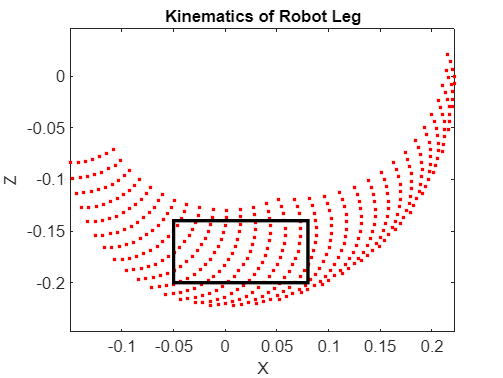


SFm = 1/1000; % mass scaling factor
mA = SFm * 60; % NEMA23 Stepper Motor, 100g

mc = SFm * 40 + mA; % mass of coxa
mt = SFm * 31 + mA;% mass of thigh according to SLDWRKS is 30.89 g
ms = SFm * 49 ;% mass of shin according to SLDWRKS is 48.97 g


m =   2*6*(mc+mt+ms)+SFm*500 ;% kilograms bearing platform


alpha = 0 ;% maximum slope in degrees
v = 0.1 ;% max velocity

G = 9.81*m;
Gc = 9.81*mc;
Gt = 9.81*mt;
Gs = 9.81*ms;
GA = 9.81*mA;
rbp = SFl*0.3;

lGx = lt.*sin(betadash)+ls.*sin(beta); %distance from vector G's Xg component to the top foothold
lGz = rbp+lc+lt.*cos(betadash)+ls.*cos(beta); %distance from vector G's Zg component to the top foothold
lez1 = 2*(lc+lt.*cos(betadash)+ls.*cos(beta))+rbp*1.5; %distance of FeIz1 to top foothold (oeI4)

Fez1 = (G*sin(alpha).*lGx + G*(cosd(alpha)).*lGz)./lez1; % equivalent contact force

%Fz1 = Fez1/(4*cos(alpha)); 
Fz1 = Fez1/2;
% Force of foothold of leg 1 in direction Z assuming that at most, 
% half the weight of the robot is resting on one leg
Fx1 = G*sind(alpha)/4; % '' in direction X


hold off

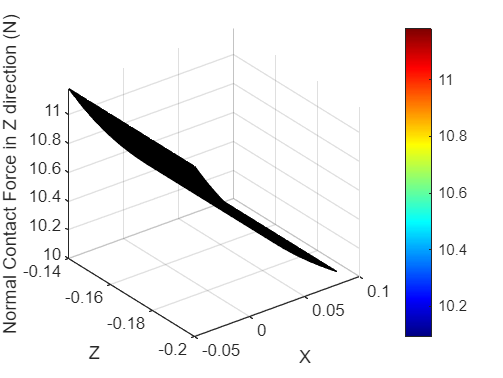

figure(2);
surf(X1,Y1,Fz1);
xlabel('X');
ylabel('Z');
zlabel('Normal Contact Force in Z direction (N)');
colormap("jet")
colorbar;

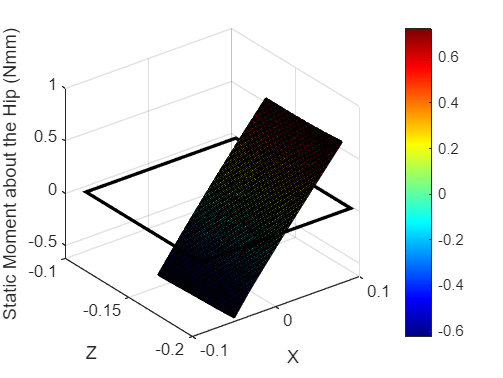

[F_max, F_Max_Idx] = max(abs(Fz1(:)));
[F_maxRow,F_maxCol] = ind2sub(size(Fz1), F_Max_Idx);
[F_min, F_min_Idx] = min(abs(Fz1(:)));
[F_minRow,F_minCol] = ind2sub(size(Fz1), F_min_Idx);

maxBetaForce = rad2deg(beta(F_maxRow,F_maxCol));
maxBetaDashForce = rad2deg(betadash(F_maxRow,F_maxCol));

minBetaForce = rad2deg(beta(F_minRow,F_minCol));
minBetaDashForce = rad2deg(betadash(F_minRow,F_minCol));

lz_hip = (lt.*cos(betadash)+ls.*cos(beta)); % matrix of distance between Force in Z direction and axes of joints
lz_knee = (ls.*cos(beta)); % matrix of distance between Force in Z direction and axes of joints
lx_hip = lt.*sin(betadash)+ls.*sin(beta); % matrix of distance between Force in X dir and axes of joints
lx_knee = ls.*sin(beta); % matrix of distance between Force in X dir and axes of joints
lGt_hip = abs(lt.*cos(alpha+betadash)./2); % matrix of distance between mass of thigh vector and joints
lGt_knee = abs(0.*betadash); % matrix of distance between mass of thigh vector and joints
lGs_hip = abs(lt.*cos(alpha+betadash)+(ls.*cos(alpha+beta)./2)); % matrix of distance between mass of shin vector and joints
lGs_knee = abs(lt.*cos(alpha+beta)./2); % matrix of distance between mass of shin vector and joints

lGA_hip = lGt_hip.*2;
lGA_knee = lGt_knee.*2;

%Mh1 = Fz1.*lz_hip-Fx1.*lx_hip-Gt.*lGt_hip-Gs.*lGs_hip
Mh1 = Fz1.*lz_hip-Fx1.*lx_hip-Gt.*lGt_hip-Gs.*lGs_hip-GA.*lGA_hip; % Moment vector of hip and knee joints
figure(3);
%surf(betadash, beta, Mh1)

limit_knee = abs(Mh1) > 0.5;
Mh2 = Mh1;
Mh2(limit_knee) = NaN;

surf(X1,Y1,Mh1)
xlabel('X');
ylabel('Z');
zlabel('Static Moment about the Hip (Nmm)');
colormap("jet")
colorbar;
rectangle('Position', [-0.0825 -0.195 0.180 0.090], 'LineWidth',2) % [-5 -7] [7 -7] [7 -13.5] [-5 -13.5]

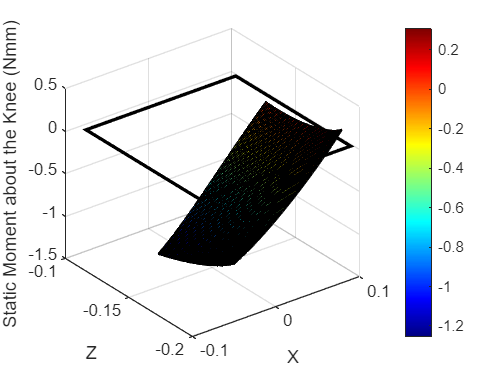


[Mh_max, Mh_Idx] = max(abs(Mh1(:)));
Mh_max;
[Mh_maxRow,Mh_maxCol] = ind2sub(size(Mh1), Mh_Idx);
[Mh_min, Mh_Min_Idx] = min(abs(Mh1(:)));
Mh_min;
[Mh_minRow,Mh_minCol] = ind2sub(size(Mh1), Mh_Min_Idx);

Mk1 = Fz1.*lz_knee-Fx1.*lx_knee-Gt.*lGt_knee-Gs.*lGs_knee-GA.*lGA_knee;
%Mk1 = Fz1.*lz_knee-Fx1.*lx_knee-Gt.*lGt_knee-Gs.*lGs_knee;
limit_knee = abs(Mk1) > 0.5;
Mk2 = Mk1;
Mk2(limit_knee) = NaN;

figure(4);
surf(X1, Y1, Mk1)
xlabel('X');
ylabel('Z');
rectangle('Position', [-0.0825 -0.195 0.180 0.090], 'LineWidth',2) % [-5 -7] [7 -7] [7 -13.5] [-5 -13.5]

zlabel('Static Moment about the Knee (Nmm)');
colormap("jet")
colorbar;

[Mk_max, Mk_Max_Idx] = max(abs(Mk1(:))); % max and index
Mk_max;
[Mk_maxRow,Mk_maxCol] = ind2sub(size(Mk1), Mk_Max_Idx);
[Mk_min, Mk_Min_Idx] = min(abs(Mk1(:)));
Mk_min;
[Mk_minRow,Mk_minCol] = ind2sub(size(Mk1), Mk_Min_Idx);

maxBetaHip = rad2deg(beta(Mh_maxRow,Mh_maxCol));
maxBetaDashHip = rad2deg(betadash(Mh_maxRow,Mh_maxCol));

minBetaHip = rad2deg(beta(Mh_minRow,Mh_minCol));
minBetaDashHip = rad2deg(betadash(Mh_minRow,Mh_minCol));
xt_min=(lt*cosd(-minBetaDashHip)); % betadash
yt_min=(lt*sind(-minBetaDashHip)); 
xs_min=xt_min+(ls*cosd(-minBetaHip)) ;% beta
ys_min=yt_min+(ls*sind(-minBetaHip));

xt_max=(lt*cosd(-maxBetaDashHip)); % betadash
yt_max=(lt*sind(-maxBetaDashHip)); 
xs_max=xt_max+(ls*cosd(-maxBetaHip)); % beta
ys_max=yt_max+(ls*sind(-maxBetaHip));



figure(6)
hold on
plot([0 xt_max],[0 yt_max],'y-o', 'LineWidth',3);
plot([xt_max xs_max],[yt_max ys_max],'y-o', 'LineWidth',3);

plot([0 xt_min],[0 yt_min],'r-o', 'LineWidth',3);
plot([xt_min xs_min],[yt_min ys_min],'r-o', 'LineWidth',3);

%%%

maxBetaKnee = rad2deg(beta(Mk_maxRow,Mk_maxCol));
maxBetaDashKnee = rad2deg(betadash(Mk_maxRow,Mk_maxCol));
minBetaKnee = rad2deg(beta(Mk_minRow,Mk_minCol));
minBetaDashKnee = rad2deg(betadash(Mk_minRow,Mk_minCol));

xt_max_knee=(lt*cosd(-maxBetaDashKnee)); % betadash
yt_max_knee=(lt*sind(-maxBetaDashKnee)); 
xs_max_knee=xt_max_knee+(ls*cosd(-maxBetaKnee)); % beta
ys_max_knee=yt_max_knee+(ls*sind(-maxBetaKnee));

Moments = abs(Mk1)+abs(Mh1);
[lowestM, bestIdx] = min(abs(Moments(:)));
[bestRow, bestCol] = ind2sub(size(Moments), bestIdx);
bestBeta = rad2deg((beta(bestRow,bestCol)));
bestDash = rad2deg((betadash(bestRow,bestCol)));

xt_min_knee=(lt*cosd(-minBetaDashKnee)); % betadash
yt_min_knee=(lt*sind(-minBetaDashKnee)); 
xs_min_knee=xt_min_knee+(ls*cosd(-minBetaKnee)) ;% beta
ys_min_knee=yt_min_knee+(ls*sind(-minBetaKnee));



plot([0 xt_max_knee],[0 yt_max_knee],'b-o', 'LineWidth',3)
plot([xt_max_knee xs_max_knee],[yt_max_knee ys_max_knee],'b-o', 'LineWidth',3)

plot([0 xt_min_knee],[0 yt_min_knee],'g-o', 'LineWidth',3)
plot([xt_min_knee xs_min_knee],[yt_min_knee ys_min_knee],'g-o', 'LineWidth',3)

plot([0 -lc],[0,0],'black-o','LineWidth',3)

xt_best=(lt*cosd(-bestDash)); % betadash
yt_best=(lt*sind(-bestDash)); 
xs_best=xt_best+(ls*cosd(-bestBeta)); % beta
ys_best=yt_best+(ls*sind(-bestBeta));

bestAtHip = Mh1(bestRow,bestCol);
bestAtKnee = Mk1(bestRow,bestCol);

plot([0 xt_best],[0 yt_best],'black-o', 'LineWidth',3)
plot([xt_best xs_best],[yt_best ys_best],'black-o', 'LineWidth',3)
rectangle('Position', [-0.05 -0.2 0.13 0.06], 'LineWidth',2) % [-5 -7] [7 -7] [7 -13.5] [-5 -13.5]
ylim([-0.200 .100])
xlim([-.200 .100])

titles = ["";"Value";"X";"Z";"Betadash";"Beta"];

HipMax = ["Max Hip"; Mh_max; xs_max; ys_max;maxBetaDashHip;maxBetaHip];
HipMin = ["Min Hip"; Mh_min; xs_min; ys_min;minBetaDashHip;minBetaHip];
KneeMax = ["Max Knee"; Mk_max; xs_max_knee; ys_max_knee;maxBetaDashKnee;maxBetaKnee];
KneeMin = ["Min Knee"; Mk_min; xs_min_knee; ys_min_knee;minBetaDashKnee;minBetaKnee];
Best = ["Best Angles";lowestM;xs_best;ys_best;bestDash;bestBeta];
table(titles, HipMax, HipMin, KneeMax, KneeMin, Best)

ans = 6×6 table
      titles       HipMax         HipMin        KneeMax        KneeMin           Best     
    __________    _________    ____________    __________    ____________    _____________

    ""            "Max Hip"    "Min Hip"       "Max Knee"    "Min Knee"      "Best Angles"
    "Value"       "0.72525"    "0.00021017"    "1.2543"      "1.9477e-05"    "0.43654"    
    "X"           "0.08"       "0.008"         "-0.05"       "0.066"         "0.006"      
    "Z"           "-0.2"       "-0.171"        "-0.14"       "-0.18"         "-0.2"       
    "Betadash"    "47.1824"    "26.3934"       "32.6736"     "24.4433"       "50.0566"    
    "Beta"        "78.1806"    "112.3101"      "137.7471"    "90.0007"       "105.683"    


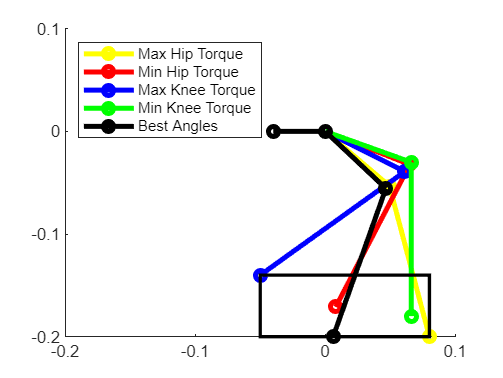




legend({'Max Hip Torque','','Min Hip Torque','','Max Knee Torque','','Min Knee Torque','','Best Angles',''}, 'Location','northwest')